# Tumor brain MRI images segmentation

### Introduction

In the domain of digital image processing, sometimes we need to separate the main object from the image for clear observation. 

**Image segmentation **is the process that enables this partitioning. In this method, each pixel is assigned a label, and pixels that share some characteristics are assigned the same label number. This technique is widely used in the medical domain to locate the object of interest.

### What is medical imaging?

This term refers to the technique which medical professionals use to view inside the human body in order to diagnose, monitor, and treat. There are various techniques available in the modern scientific age.

- **MRI:** Magnetic resonance imaging

- **CT Scan:** Computed Tomography Scan

- **X-Ray:** Using electromagnetic waves called X-rays.

- **Ultrasound:** Uses sound waves to create pictures of inner body tissues. It does not use any radiation.

There are different types of images segmentation:

- Thresholding Segmentation

- Edge-Based Segmentation

- Region-Based Segmentation

- Watershed Segmentation

MRI scan images of the brain. This method incorporates with, segmentation and morphological operations which are the basic concepts of image processing. 

Detection and extraction of tumour from MRI scan images of the brain is done by using MATLAB software. We first want concentrate creating a code which requires a small processing time for result .

## Steps of the code

### Step 1: Finding Proper MRI Images

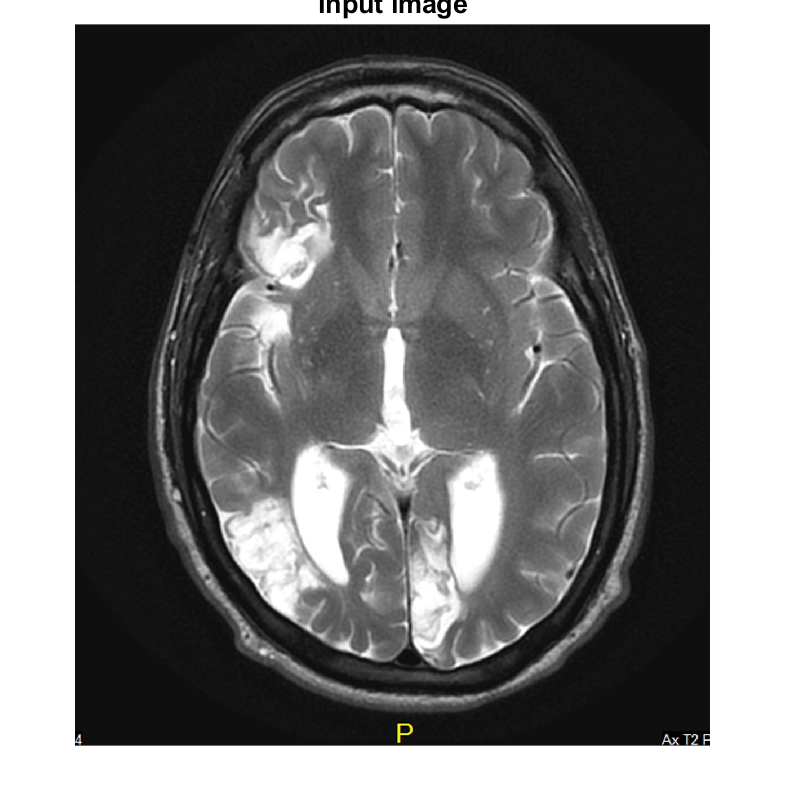

clc
close all
clear all
% Input
[I,path]=uigetfile('*.jpg','select a input image');
str=strcat(path,I);
s=imread(str);
figure;
imshow(s);
title('Input image','FontSize',20);

#### Suggestion:

If you want to dispaly and do some operations on the image itself, it could be also useful to use the **imtool function** which is directly linked to the image processing tool of matlab and you can directly do on the image some of the operation that we are going to discuss.

### **Step 2: Apply a filter to the image**

num_iter = 10;
    delta_t = 1/7;
    kappa = 15;
    option = 2;
    disp('Preprocessing image please wait . . .');

Preprocessing image please wait . . .


    inp = anisodiff(s,num_iter,delta_t,kappa,option);

Removing noise
Filtering Completed !!

    inp = uint8(inp); 

Because there are 8 bit s in the binary representation of the gray level, this imaging method is called 8-bit grayscale. 

#### Anisotropic diffusion

Anisotropic diffusion is a powerful image enhancer and restorer based on the PDE of heat transfer. By means of an edge-stopping function (ESF), this filter is capable of smoothing noisy pixels, while preserving the intensity of most edges.

So, basically it simply removes noise from the MRI images. Anisotropic diffusion can be used to remove noise from digital images without blurring edges.

 

Equation of an anisotropic filter where $\Delta$ denotes the [Laplacian](https://en.wikipedia.org/wiki/Laplacian), $\nabla$ denotes the [gradient](https://en.wikipedia.org/wiki/Gradient), div (...)  is the [divergence](https://en.wikipedia.org/wiki/Divergence) operator and c(x,y,t) is the diffusion coefficient (denoted for us as kappa coefficient).

[Anysotropic function](https://www.mathworks.com/matlabcentral/fileexchange/31204-anisodiff-in-matlab) Link

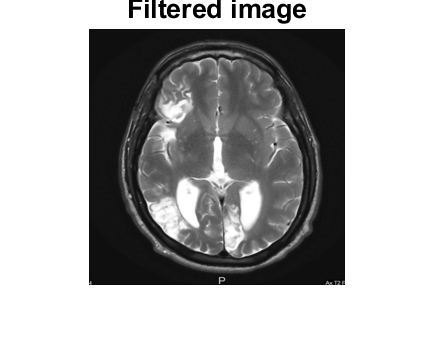

inp=imresize(inp,[256,256]);
if size(inp,3)>1
    inp=rgb2gray(inp);
end
figure;
imshow(inp);
title('Filtered image','FontSize',20);

### Step 3: compute threshold segmentation

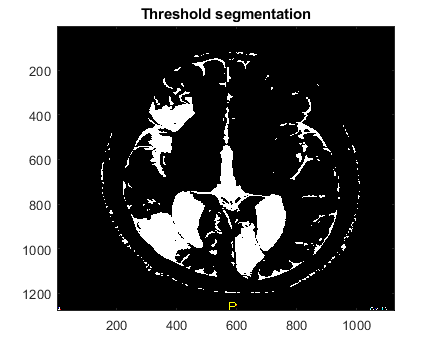

sout=imresize(inp,[256,256]);
t0=mean(s(:));
th=t0+((max(inp(:))+min(inp(:)))./2);
for i=1:1:size(inp,1)
    for j=1:1:size(inp,2)
        if inp(i,j)>th
            sout(i,j)=1;
        else
            sout(i,j)=0;
        end
    end
end
figure(2);
thresha = s>150 & s< 260;
imagesc(thresha);
colormap(gray);
title 'Threshold segmentation'

### Step 4: Morphological Operation

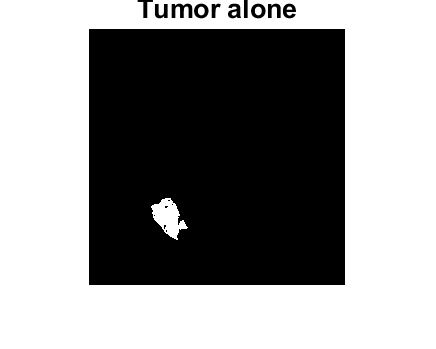

label=bwlabel(sout);
stats=regionprops(logical(sout),'Solidity','Area','BoundingBox');
density=[stats.Solidity];
area=[stats.Area];
high_dense_area=density>0.7;
max_area=max(area(high_dense_area));
tumor_label=find(area==max_area);
tumor=ismember(label,tumor_label);

if max_area>200
   figure;
   imshow(tumor)
   title('Tumor alone','FontSize',20);
else
    h = msgbox('No Tumor!!','status');
    %disp('no tumor');
    return;
end

#### Additional feature: how to create a bounding box

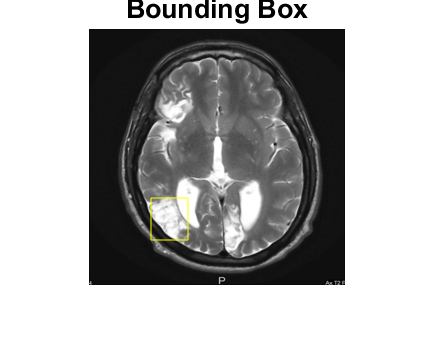

box = stats(tumor_label);
wantedBox = box.BoundingBox;
figure
imshow(inp);
title('Bounding Box','FontSize',20);
hold on;
rectangle('Position',wantedBox,'EdgeColor','y');
hold off;

It is also possible to create manually a bounding box by using the createmask function as follows:

%% I draw the rectangle
%r = drawrectangle; 
% I create a mask of it that i will process then on the original image, in
%% this case the filtered one
%mask = createMask(r); 
%% and then you create the contour by using the appropiate function!

### Step 5: Watershed Segmentation

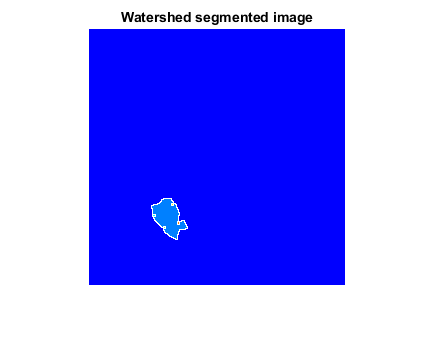

hy = -fspecial('sobel');
hx = hy';
Iy = imfilter(double(tumor), hy, 'replicate');
Ix = imfilter(double(tumor), hx, 'replicate');
gradmag = sqrt(Ix.^2 + Iy.^2);
L = watershed(gradmag);
Lrgb = label2rgb(L);

figure,
    imshow(Lrgb); 
    title('Watershed segmented image');

### Step 6: Getting Tumor Outline - image filling, eroding, subtracting erosion the walls by a few pixels

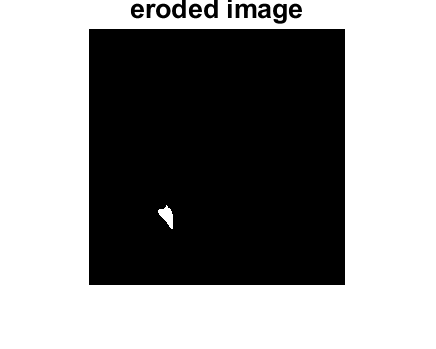

dilationAmount = 5;
rad = floor(dilationAmount);
[r,c] = size(tumor);
filledImage = imfill(tumor, 'holes');

for i=1:r
   for j=1:c
       x1=i-rad;
       x2=i+rad;
       y1=j-rad;
       y2=j+rad;
       if x1<1
           x1=1;
       end
       if x2>r
           x2=r;
       end
       if y1<1
           y1=1;
       end
       if y2>c
           y2=c;
       end
       erodedImage(i,j) = min(min(filledImage(x1:x2,y1:y2)));
   end
end
figure
imshow(erodedImage);
title('eroded image','FontSize',20);

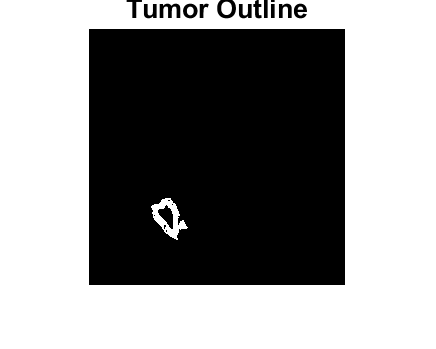

% subtracting eroded image from original BW image

tumorOutline=tumor;
tumorOutline(erodedImage)=0;

figure;  
imshow(tumorOutline);
title('Tumor Outline','FontSize',20);

Inserting the outline in filtered image in red color

rgb = inp(:,:,[1 1 1]);
red = rgb(:,:,1);
red(tumorOutline)=255;
green = rgb(:,:,2);
green(tumorOutline)=0;
blue = rgb(:,:,3);
blue(tumorOutline)=0;

tumorOutlineInserted(:,:,1) = red; 
tumorOutlineInserted(:,:,2) = green; 
tumorOutlineInserted(:,:,3) = blue; 

## Step 7: Display results

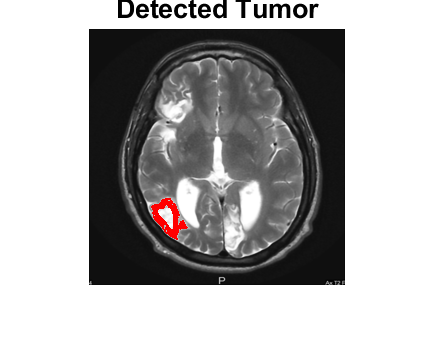

figure
imshow(tumorOutlineInserted);
title('Detected Tumor','FontSize',20);

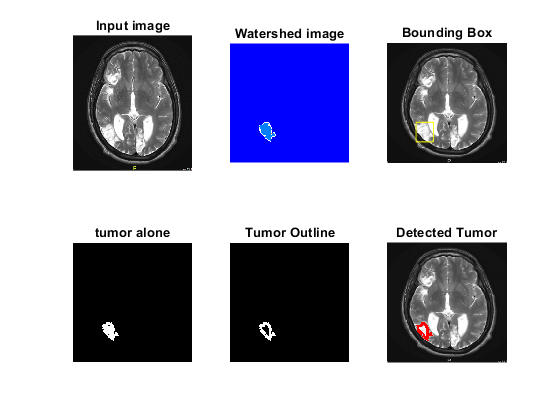

figure
subplot(231); imshow(s); title('Input image','FontSize',10);
subplot(232); imshow(Lrgb); title('Watershed image','FontSize',10);

subplot(233); imshow(inp); title('Bounding Box','FontSize',10);
hold on; 
rectangle('Position',wantedBox,'EdgeColor','y');
hold off;

subplot(234); imshow(tumor); title('tumor alone','FontSize',10);
subplot(235); imshow(tumorOutline); title('Tumor Outline','FontSize',10);
subplot(236); imshow(tumorOutlineInserted); title('Detected Tumor','FontSize',10);